## Quadcopter & Payload Reachability Analysis 

Group: Calum, Ruchira, Julia

This notebook (MATLAB live script) demonstrates a reachability analysis for our 2D quadcopter with a tethered payload

The sections below include: 

- System parameter definition

- Full nonlinear 10-state dynamics

- Auto-linearisation using symbolic Jacobians (find A and B matrices...) - much quicker than doing by hand! 

- Verification specification setup

- Linear & nonlinear reachability using CORA

- Comparison of linear and nonlinear reachable sets

Later I would like to add: 

- Closed-loop control verification with PID

- Closed-loop control verification with NN controller

clear; clc;

### System Parameters

% Physical parameters
m_q  = 1.5;      % quadcopter mass (kg)
m_p  = 0.25;     % payload mass (kg)
ell  = 1.0;      % rope length (m)
g    = 9.81;     % gravity
I_q  = 0.03;     % quad pitch inertia (kg·m²)

% Initial conditions
xq0  = 0;
zq0  = 5;
th0  = 0;

xd0  = 0;
zd0  = 0;
thd0 = 0;

phi0 = 0;      % initial payload swing angle (rad)
Ld0  = 0;        % rope velocity
phid0= 0;        % swing angular rate

### Full non-linear state model

Our state vector is defined as:

### 
$$x={\left\lbrack x_q ,z_{q,} \;\theta ,\dot{\;x_q } ,\dot{\;z_q } ,\dot{\theta} ,l,\phi ,\dot{\;l} ,\dot{\;\phi } \right\rbrack }^{T\;}$$


Our control vector is defined as:

### 
$$u={\left\lbrack T_1 ,T_2 ,T_3 ,T_4 ,u_L \right\rbrack }^{T\;}$$


### Implementing the non-linear dynamics...

f = @(x,u) quad_payload_dynamics(x,u,m_q,m_p,g,I_q);
sysNL = nonlinearSys(f);

Where we define the dynamics in a helper function:

function dx = quad_payload_dynamics(x,u,m_q,m_p,g,I_q)

    % State unpack
    xq = x(1);  zq = x(2);  th = x(3);
    xd = x(4);  zd = x(5);  thd = x(6);
    L  = x(7);  phi = x(8); Ld = x(9); phid = x(10);

    T1=u(1); T2=u(2); T3=u(3); T4=u(4); uL=u(5);

    % Thrust & torque
    T  = T1+T2+T3+T4;
    tau = (T1+T2 - T3 - T4)*0.2;  % arm length = 0.2 m

    % Rope geometry
    uvec = [sin(phi); -cos(phi)];
    tvec = [cos(phi); sin(phi)];

    % Quad acceleration
    xdd = -(T*sin(th))/m_q + (0)*1;   % add tension later
    zdd =  (T*cos(th))/m_q - g;

    % Payload acceleration
    pdd = [xdd; zdd] ...
        + (Ld^2)*uvec + L*phid^2 * (-uvec) ...
        + L*phid * tvec;

    % Tangential equation:
    phidd = -(g/L)*sin(phi) - (xdd*cos(phi) - zdd*sin(phi))/L;

    % Rope length dynamics (zero feed rate for now)
    Ldd = uL;

    dx = [ xd; zd; thd;
           xdd; zdd; tau/I_q;
           Ld;  phid; Ldd; phidd ];
end

### Define equilibrium for linearisation

e.g. Hover equilibrium: thrust balances total weight, all angles zero

x_eq = [0; 5; 0; 0; 0; 0; ell; 0; 0; 0];

Setting up verification specification...


T_hover = (m_q + m_p)*g/4;
u_eq = [T_hover; T_hover; T_hover; T_hover; 0];

### Auto-linearisation using symbolic toolbox

syms X [10 1] real
syms U [5 1] real

f_sym = quad_payload_dynamics(X,U,m_q,m_p,g,I_q);

A_sym = jacobian(f_sym, X);
B_sym = jacobian(f_sym, U);

A = double(subs(A_sym, [X;U], [x_eq; u_eq]));
B = double(subs(B_sym, [X;U], [x_eq; u_eq]));

### Build CORA linear system

sysL = linearSys(A,B);

### Initial set

x0 = x_eq;
dx0 = [0.1*ones(6,1); 0.01; 0.2; 0.01; 0.1];  % uncertainty tube

params.R0 = zonotope([x0, diag(dx0)]);

### Reachability settings

params.tFinal = 2;
options.timeStep = 0.002; 
options.taylorTerms = 4;
options.zonotopeOrder = 20;

%below needed for non-linear reachability
options.alg = 'poly';        % or 'taylor'
options.tensorOrder = 3;     
options.errorOrder = 3;
options.intermediateOrder = 3;

### Run linear reachability

Outdated: I have implemented verification against a spec too. See below...

% tic;
% disp("Running linear reachability...");
% [R,res] = reach(sys, params, options);
% disp("Linear Result: " + string(res));
% toc;

### Run non-linear reachability

% tic;
% disp("Running non-linear reachability...");
% [RNL,resNL] = reach(sysNL, params, options);
% disp("Nonlinear Result: " + string(resNL));
% toc;

Running reachability verification (linear)...


### Verification Specification

disp("Setting up verification specification...")

% Unbounded dimensions represented by [-inf, inf]

Elapsed time is 12.440412 seconds.


INF = 1e6;  % CORA does NOT allow true Inf

lb_goal = -INF*ones(10,1);
ub_goal =  INF*ones(10,1);

% Replace dimensions 1 and 2 with your actual bounds
lb_goal(1) = -0.5;   % x_q lower

Result: Verification FAILURE


ub_goal(1) =  0.5;   % x_q upper
lb_goal(2) =  4.5;   % z_q lower
ub_goal(2) =  5.5;   % z_q upper


  interval with properties:

    inf: 1.9980
    sup: 2



goalSet = interval(lb_goal, ub_goal);

% Interpretation: keep quad within 0.5 m of origin and 1 m altitude band

Running reachability verification (nonlinear)...



lb_avoid = -INF*ones(10,1);
ub_avoid =  INF*ones(10,1);

Elapsed time is 161.465464 seconds.



lb_avoid(1) = 1.5;   % x_q
ub_avoid(1) = 3.0;

lb_avoid(2) = 0.5;   % z_q
ub_avoid(2) = 3.0;

Result: Verification FAILURE



avoidSet = interval(lb_avoid, ub_avoid);

% Example: quad MUST NOT go into area x∈[1.5,3], z∈[0.5,3]

  interval with properties:

    inf: 1.9980
    sup: 2




% Build specs with time bounds
% Be in the safeSet by tFinal
spec1 = specification(goalSet,  'safeSet',   interval(params.tFinal));
% Always avoid the unsafeSet
spec2 = specification(avoidSet, 'unsafeSet', interval(0, params.tFinal));

Simulating nonlinear system...



spec = add(spec1, spec2);


Simulating linear system...


### Verification using linear reachability 

disp("Running reachability verification (linear)...");
tic;
[R,resL] = reach(sysL, params, options, spec);
toc;

Plotting linear vs nonlinear reachable sets side-by-side...




if resL
    disp("Result: Verification SUCCESS")
else
    disp("Result: Verification FAILURE")
end

[R_nospec,~] = reach(sysL, params, options);

disp(R_nospec.timeInterval.time{end})

### Verification using non-linear reachability

disp("Running reachability verification (nonlinear)...");
tic;
[RNL, resNL] = reach(sysNL, params, options, spec);
toc;

if resNL
    disp("Result: Verification SUCCESS")
else
    disp("Result: Verification FAILURE")
end

[RNL_nospec,~] = reach(sysNL, params, options);

disp(RNL.timeInterval.time{end})

### Simulation for comparison 

simOpt.points = 20;
simOpt.type = 'gaussian';

disp("Simulating nonlinear system...")
simResNL = simulateRandom(sysNL, params, simOpt);

disp("Simulating linear system...")
simResL = simulateRandom(sysL, params, simOpt);

### Plot: Comparison of linear and non-linear reachable sets

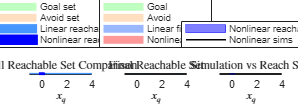

disp("Plotting linear vs nonlinear reachable sets side-by-side...")

figure('Position',[200 200 1500 550]);
tiledlayout(1,3,'Padding','compact','TileSpacing','compact')

dims = [1 2];   % Compare x_q vs z_q
xLimits = [-1 4];
zLimits = [-1 6];

%% ======================= =====================================
% Panel 1 — Full reachable sets: linear vs nonlinear
%% ============================================================
nexttile; hold on; box on; grid on;

title("Full Reachable Set Comparison","Interpreter","latex")

% Safe + unsafe sets
plot(spec1, dims,'FaceColor',[0 1 0 .25],'EdgeColor','none','DisplayName','Goal set');
plot(spec2, dims,'FaceColor',[1 .5 0 .25],'EdgeColor','none','DisplayName','Avoid set');

% Linear reach set
useCORAcolors("CORA:contDynamics");
plot(R, dims, 'LineWidth', 1.0, ...
     'DisplayName','Linear reachable', ...
     'Unify',true,'UnifyTotalSets',5);

% Nonlinear reach set
plot(RNL, dims, 'LineWidth', 2.0, 'Color',[0 0 1], ...
     'DisplayName','Nonlinear reachable', ...
     'Unify',true,'UnifyTotalSets',5);

xlabel('$x_q$','Interpreter','latex')
ylabel('$z_q$','Interpreter','latex')
xlim(xLimits); ylim(zLimits)
legend('Location','northoutside','Orientation','vertical');


%% ============================================================
% Panel 2 — Final reachable sets
%% ============================================================

nexttile; hold on; box on; grid on;

title("Final Reachable Set","Interpreter","latex")

plot(spec1, dims,'FaceColor',[0 1 0 .25],'EdgeColor','none','DisplayName','Goal');

Plotting reachable set over time...


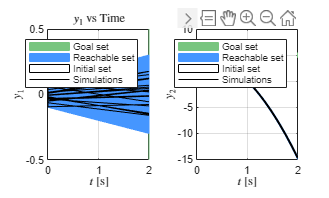

plot(spec2, dims,'FaceColor',[1 .5 0 .25],'EdgeColor','none','DisplayName','Avoid');

finalLin  = R.timePoint.set{end,1};
finalNonL = RNL.timePoint.set{end,1};

plot(finalLin,  dims, 'FaceColor',[0 .3 1 .40], 'EdgeColor','none', ...
    'DisplayName','Linear final');
plot(finalNonL, dims, 'FaceColor',[1 0 0 .40], 'EdgeColor','none', ...
    'DisplayName','Nonlinear final');

xlabel('$x_q$','Interpreter','latex')
ylabel('$z_q$','Interpreter','latex')
xlim(xLimits); ylim(zLimits)
legend('Location','northoutside','Orientation','vertical');


%% ============================================================
% Panel 3 — Simulation trajectories vs reach sets
%% ============================================================
nexttile; hold on; box on; grid on;

title("Simulation vs Reach Sets","Interpreter","latex")

% Plot nonlinear reach boundary
plot(RNL, dims,'Color',[0 0 1 .5], ...
    'DisplayName','Nonlinear reachable', ...
    'Unify',true,'UnifyTotalSets',5);

% Simulation traces (nonlinear)
plot(simResNL, dims, 'k','LineWidth',1.2, 'DisplayName','Nonlinear sims');


xlabel('$x_q$','Interpreter','latex')
ylabel('$z_q$','Interpreter','latex')
xlim(xLimits); ylim(zLimits)
legend('Location','northoutside','Orientation','vertical');

Plotting state projection for non-linear system...


### Plot: time histories

This plots evolution of two dimensions (x and z):

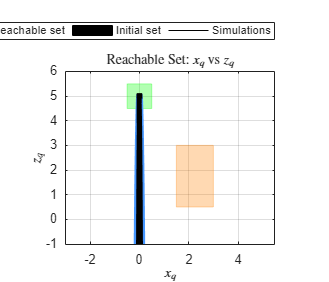

disp("Plotting reachable set over time...")

dims = [1 2];   % x_q → y_1 , z_q → y_2

figure; tiledlayout(1,2)

for k = 1:2
    nexttile; hold on; box on; grid on;

    % Safe set band
    plotOverTime(spec1, k, 'DisplayName', 'Goal set');

    % Correct LaTeX title
    title(sprintf('$y_{%d}$ vs Time', dims(k)), 'Interpreter','latex')

    % Reachable set
    useCORAcolors("CORA:contDynamics")
    plotOverTime(RNL, k, 'DisplayName', 'Reachable set');

    % Initial set
    plotOverTime(RNL(1).R0, k, 'DisplayName', 'Initial set');

    % Random simulations
    plotOverTime(simResNL, k, 'DisplayName', 'Simulations');


    % Correct LaTeX label
    ylabel(sprintf('$y_{%d}$', dims(k)), 'Interpreter','latex')

Plotting state projection for linear system...


    xlabel('$t$ [s]', 'Interpreter','latex')

    xlim([0 params.tFinal])
    legend
end


### Plot: 2D state projection (quad x vs z)

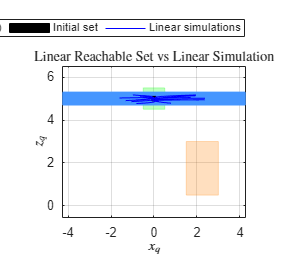

disp("Plotting state projection for non-linear system...")

dims = [1 2];   % x_q and z_q

figure('Position',[200 200 700 600]); hold on; box on; grid on;

xLimits = [-1  4];     % quad x range
zLimits = [-1  6];     % quad z range

% Goal & avoid sets
plot(spec1, dims, 'FaceColor',[0 1 0 .3], 'DisplayName','Goal set');
plot(spec2, dims, 'FaceColor',[1 0.5 0 .3],'DisplayName','Avoid set');

useCORAcolors("CORA:contDynamics")
plot(RNL, dims, 'DisplayName','Reachable set', ...
     'Unify',true,'UnifyTotalSets',5);

plot(RNL(1).R0, dims, 'k','DisplayName','Initial set');
plot(simResNL, dims, 'k','DisplayName','Simulations');


xlabel('$x_q$','Interpreter','latex')
ylabel('$z_q$','Interpreter','latex')
title("Reachable Set: $x_q$ vs $z_q$",'Interpreter','latex')
xlim(xLimits); ylim(zLimits);
legend('Location','northoutside','Orientation','horizontal')
axis equal

Plot: linear reachable set vs linear sim

disp("Plotting state projection for linear system...")

dims = [1 2];   % x_q and z_q

figure('Position',[200 200 700 600]); hold on; box on; grid on;

% Goal & avoid sets
plot(spec1, dims, 'FaceColor',[0 1 0 .25], 'DisplayName','Goal set');
plot(spec2, dims, 'FaceColor',[1 .5 0 .25],'DisplayName','Avoid set');

% Reachable set
useCORAcolors("CORA:contDynamics")
plot(R, dims, 'DisplayName','Reachable set (linear)', ...
     'Unify',true,'UnifyTotalSets',8);

% Initial set
plot(R(1).R0, dims, 'k','DisplayName','Initial set');

% Linear simulations
plot(simResL, dims, 'b','DisplayName','Linear simulations');

xlabel('$x_q$','Interpreter','latex')
ylabel('$z_q$','Interpreter','latex')
title("Linear Reachable Set vs Linear Simulation",'Interpreter','latex')

legend('Location','northoutside','Orientation','horizontal')
axis equal
